N0 = 3

N0 = 3

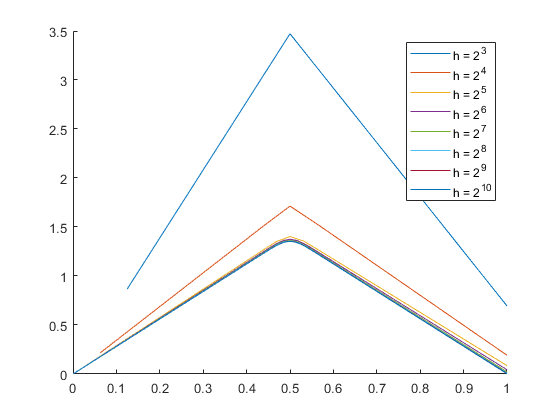

N1 = 10;
miderror = [];
mid = 1.351247804099482;
LegendNames = [];
figure()
hold on
for N=N0:N1
    h = 2^-N; %step size
    L = 1/h;  %number of steps
        
    A_temp = zeros(L); %empty Ah matrix
    for i = 1 : L
        if (i+1) <= L
            A_temp(i,i+1) = -1;
        end
        if (i-1) > 0
            A_temp(i,i-1) = -1;
        end
        A_temp(i,i) = 2;
    end
    
    A = A_temp / h^2;% resulting A matrix
    %computing values for f(xi)
    x = zeros(L,1);
    f = zeros(L,1);
    
    for i=1:L
        x(i) = i/L;
        f(i) = 100*exp(-1000*(x(i)-0.5)^2);
    end

    U =  A\f;
    
    
    plot(x,U)
    LegendNames = [LegendNames; "h = 2^{" + string(N) + "}"];
    miderror = [miderror; U(L/2)-mid];
end
legend(LegendNames)


miderror

miderror =     2.1210
    0.3619
    0.0518
    0.0236
    0.0114
    0.0056
    0.0028
    0.0014


errorstep =      1.706131396830481e-01     1.432259733463287e-01     4.562148862784347e-01     4.810388175129318e-01     4.905571906843826e-01     4.952398296055441e-01     4.976042336835418e-01
